# `Chapter 11 - Thick walled cylinder multiple layers`


% A and B are Lami's eqn constant
% r is general radius
% Pa and Pb are respetive internal and external pressures
% a is internal radius 
% b is outer radius

syms sigma_r sigma_theta A B r Pa Pb a b c delta v E 


## 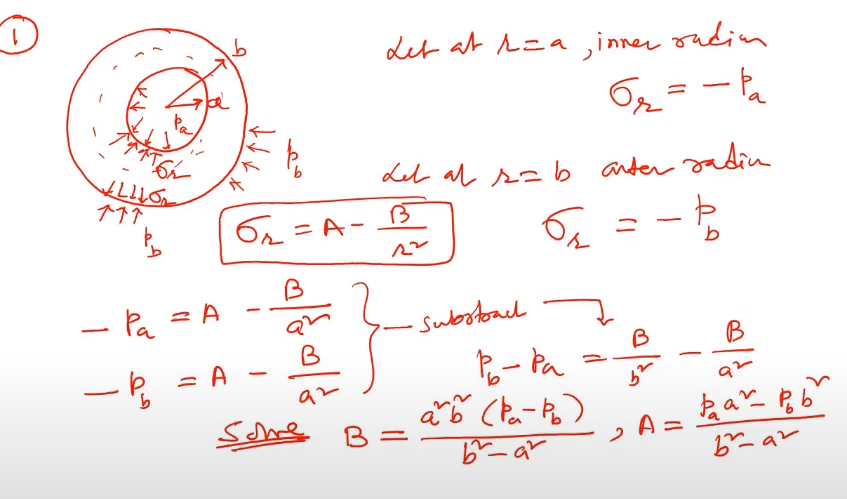

## **Here define the equations:**

eqn_r = sigma_r == A - B/r^2
eqn_theta = sigma_theta == A + B/r^2

## **Solving the equations:**

eqn1 = subs(eqn_r,sigma_r,-Pa);
eqn1 = subs(eqn1,r,a)

eqn2 = subs(eqn_r,sigma_r,-Pb);
eqn2 = subs(eqn2,r,b)

[A_mat,B_mat] = equationsToMatrix([eqn1, eqn2], [A,B]);
X = linsolve(A_mat,B_mat)


eqn_r = subs(eqn_r,A,X(1));
eqn_r = subs(eqn_r,B,X(2))

eqn_theta = subs(eqn_theta,A,X(1));
eqn_theta = subs(eqn_theta,B,X(2))

## finding particular  value by specifying value of the parameters: 

# ( ***Always remember we need to provide radius in the formula ******not the diameters)***

## **for whole cylinder**

Pa_value = ;
Pb_value = ;
r_value = ;
a_value = ;
b_value = ;
v_value = 0.33; % poisson ratio
E_value = 72*10^3;   %in MPa
delta = 0.125;


var_sub = [Pa,Pb,r,a,b]; 
var_value = []; % here specify the value of parameters
sol_eqn_r = subs(eqn_r,var_sub,var_value)
vpa(sol_eqn_r)
sol_eqn_theta = subs(eqn_theta,var_sub,var_value) 
vpa(sol_eqn_theta)

var_pc = [E delta a b c]
var_pc_value = [E,delta,a,b,c]
Pc = (E*delta/c)*[((b^2-c^2)*(c^2-a^2))/((2*c^2)*(b^2-a^2))]

var_sub_inner = [Pa,Pb,r,a,b]; 
var_value_inner = [0,pc,((150+100)*10^-3)/2,(200*10^-3)/2,(300*10^-3)/2]; % here specify the value of parameters
sol_eqn_r2 = subs(eqn_r,var_sub_inner,var_value_inner)
vpa(sol_eqn_r2)
sol_eqn_theta2 = subs(eqn_theta2,var_sub_inner,var_value_inner) 
vpa(sol_eqn_theta2)
